data_clean = airbnbdata;
data_clean = removevars(data_clean, {'NeighbourhoodCleansed', 'City', 'ReviewScoresAccuracy', 'ReviewScoresCheckin', 'ReviewScoresCleanliness', 'ReviewScoresCommunication', 'ReviewScoresLocation', 'ReviewScoresValue'});

% separates remaining columns into three types: numerical values, short
% phrases, and string lists. 
value_vars = {'HostResponseRate', 'HostListingsCount', 'Accommodates', 'Bathrooms', 'Bedrooms', 'Beds', 'Price', 'MinimumNights', 'MaximumNights', 'NumberofReviews', 'ReviewScoresRating', 'ReviewsperMonth'};
single_vars = {'HostResponseTime', 'Market', 'Country', 'PropertyType', 'RoomType', 'CancellationPolicy'};
multi_vars = {'Amenities', 'Features'};

data_values = removevars(data_clean, union(single_vars, multi_vars))

data_values = 15396×12 table
    HostResponseRate    HostListingsCount    Accommodates    Bathrooms    Bedrooms    Beds    Price    MinimumNights    MaximumNights    NumberofReviews    ReviewScoresRating    ReviewsperMonth
    ________________    _________________    ____________    _________    ________    ____    _____    _____________    _____________    _______________    __________________    _______________

          100                   3                 1               1          1         1       331           1              1125               122                  93        

data_single = removevars(data_clean, union(value_vars, multi_vars))

data_single = 15396×6 table
      HostResponseTime        Market          Country         PropertyType           RoomType         CancellationPolicy
    ____________________    ___________    _____________    _________________    _________________    __________________

    'within an hour'        undefined'     'Denmark'        'Apartment'          'Private room'           'moderate'    
    'within an hour'        undefined'     'Denmark'        'Apartment'          'Private room'           'strict'      
    'within a day'          'Amsterdam'    'Netherlands'    'Apartment'          'Entire home/apt'        'moderate'    
    'within an hour'        'Amsterdam'    'Netherlands'    'Bed & Breakfast'    'Private room'           'moderate'    
    'within a few hours'    'Amsterdam'  

data_multi = removevars(data_clean, union(single_vars, value_vars))

data_multi = 15396×2 table
                                                                                                                                                                                                          Amenities                                                                                                                                                                                                                                                        Features                                             
    ______________________________________________________________________________________________________________________________________________________________________________________________________________________________________________________________________________________________________________________________________________________________________________________________________________________


data_len = size(data_clean, 1);
max_components = 100;

% Scaling value columns down to 0 to 1: DON'T DO THIS! It skews the result.
% data_values_matrix = table2array(data_values);
% data_values_maxes = max(data_values_matrix, [], 1);
% 
% for i=1:size(data_values, 2)
%     data_values(:,i) = array2table(data_values_matrix(:,i) / data_values_maxes(i));
% end
% 
% data_values

% Multi variable calculations; convert to table format
top_len = max_components;
multi_m = [];
multi_n = {};

for i=1:size(data_multi, 2)
    [tm, tn] = one_hot_encoding_mv(strrep(string(data_multi{:,i}), '''', ''), data_len, top_len);
    multi_m = [multi_m tm];
    multi_n = [multi_n tn];
end

multi_table = array2table(multi_m, 'VariableNames', regexprep(multi_n, '[^a-zA-Z0-9]', '_'))

multi_table = 15396×108 table
    Wireless_Internet    Heating    Essentials    Kitchen    Internet    Shampoo    TV    Hair_dryer    Hangers    Washer    Iron    Family_kid_friendly    Smoke_detector    Laptop_friendly_workspace    Air_conditioning    Carbon_monoxide_detector    Dryer    has_24_hour_check_in    Fire_extinguisher    First_aid_kit    Cable_TV    Buzzer_wireless_intercom    translation_missing__en_hosting_amenity_50    Elevator_in_building    Free_parking_on_premises    translation_missing__en_hosting_amenity_49    Safety_card

% Single variable calculations; convert to table format
top_len = max_components;
single_m = [];
single_n = {};

for i=1:size(data_single, 2)
    [tm, tn] = one_hot_encoding_sv(strrep(string(data_single{:,i}), '''', ''), data_len, top_len);
    single_m = [single_m tm];
    single_n = [single_n tn];
end

single_table = array2table(single_m, 'VariableNames', regexprep(single_n, '[^a-zA-Z0-9]', '_'))

single_table = 15396×106 table
    within_an_hour    within_a_few_hours    within_a_day    a_few_days_or_more    Paris    Los_Angeles    Rome    New_York    London    Barcelona    Madrid    Venice    San_Francisco    Amsterdam    Portland    Berlin    New_Orleans    Vienna    Melbourne    D_C_    Toronto    Athens    Dublin    Chicago    Austin    Sydney    Brussels    Edinburgh    Nashville    Vancouver    Seattle    San_Diego    Copenhagen

% getting ratings and all except ratings data
data_table = [data_values single_table multi_table]

data_table = 15396×226 table
    HostResponseRate    HostListingsCount    Accommodates    Bathrooms    Bedrooms    Beds    Price    MinimumNights    MaximumNights    NumberofReviews    ReviewScoresRating    ReviewsperMonth    within_an_hour    within_a_few_hours    within_a_day    a_few_days_or_more    Paris    Los_Angeles    Rome    New_York    London    Barcelona    Madrid    Venice    San_Francisco    Amsterdam    Portland    Berlin    New_Orleans    Vienna    Melbourne


data_rating_matrix = data_values.ReviewScoresRating;
data_rating_table = array2table(data_rating_matrix, 'VariableNames', {'ReviewScoresRating'});

data_norating_table = removevars(data_table, {'ReviewScoresRating'});
data_norating_matrix = table2array(data_norating_table);

% linear regression (regress) for everything except rating to rating

% B = data_ratings_matrix\data_noratings_matrix
B = regress(data_rating_matrix,data_norating_matrix);
B'

ans =     0.0483   -0.0618   -0.3144    0.0951    0.1627   -0.0541    0.0109    0.0347   -0.0000    0.0009    0.0376   -0.1695         0    0.6609    2.6865         0   -3.8690   -8.8178   -4.9246   -2.4548   -1.0935   -0.9107   -8.9782   -3.9366         0   -2.1107         0   -2.3793    4.9872   -7.3615   -4.3565   -8.5260         0    4.1708   -3.0567   -2.9698   -8.2402   -0.0550    0.0546   -1.3491   -7.9580   -1.9859   -2.1365   -0.4508   -4.3222   -6.1883         0         0   -1.5998   -8.9386



B_stacked = [num2cell([1:size(B, 1)]); data_norating_table.Properties.VariableNames; num2cell(B')];
B_transpose = transpose(sortrows(transpose(B_stacked), 3, 'descend'));
top_attributes = B_transpose(:, 1:10)

top_attributes = 3×10 cell array
    {[        108]}    {[         107]}    {[            106]}    {[     66]}    {[     70]}    {[       71]}    {[           65]}    {[    67]}    {[            69]}    {[         80]}
    {'Shared_room'}    {'Private_room'}    {'Entire_home_apt'}    {'Italy'  }    {'Canada' }    {'Australia'}    {'United_States'}    {'Spain' }    {'United_Kingdom'}    {'Switzerland'}
    {[    83.1766]}    {[     82.7542]}    {[        82.4330]}    {[16.1179]}    {[12.5452]}    {[  11.8010]}    {[       7.9998]}    {[6.2078]}    {[        6.1655]}    {[     5.9193]}



predicted_rating = data_norating_matrix * B;
diff_rating = data_rating_matrix - predicted_rating;
output_stacked = [data_rating_matrix'; predicted_rating'; diff_rating']

output_stacked =    93.0000   89.0000   87.0000   93.0000   94.0000   95.0000   99.0000   88.0000   94.0000   94.0000   94.0000   95.0000   95.0000   97.0000   93.0000   97.0000   94.0000   94.0000   84.0000   93.0000   99.0000   95.0000   98.0000   94.0000   93.0000   91.0000   92.0000   95.0000   96.0000   93.0000   94.0000   96.0000   95.0000   93.0000   98.0000   90.0000   96.0000   93.0000   98.0000   98.0000   97.0000   97.0000   98.0000   95.0000   90.0000   98.0000   92.0000   92.0000   96.0000   96.0000
   90.9077   91.0923   90.1908   91.5265   94.2261   96.9094   98.4836   91.8880   92.0390   92.5727   94.4238   96.9795   96.6549   97.3419   92.6653   96.0653   93.2842   92.2781   90.5469   92.3383   97.3178   92.8431   98.7350   96.5018   92.9018   92.5099   94.1013   98.2433   98.2282   93.0847   93.8695   91.5654   95.2836   90.3969   97.7253   93.7757   92.5252   91.1990  100.6121   98.2425   96.8146   97.4591   98.8316   96.3878   91.5596   93.7128   92.9800   90.6527  


corr(data_rating_matrix, predicted_rating)

ans = 0.6922

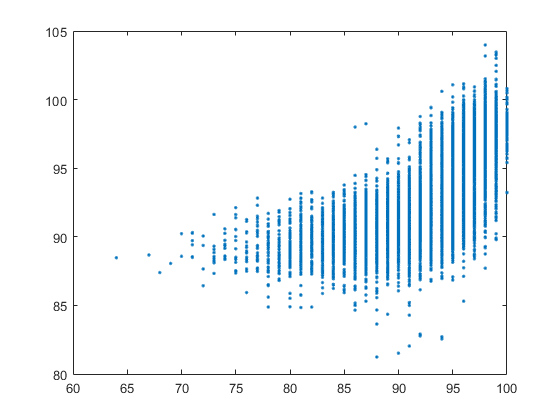

% plotting actual vs predicted rating to see error/shape of distribution
% (the more linear, the more accurate)
plot(data_rating_matrix, predicted_rating, '.')

% getting price and all except price data
data_table = [data_values single_table multi_table]

data_table = 15396×226 table
    HostResponseRate    HostListingsCount    Accommodates    Bathrooms    Bedrooms    Beds    Price    MinimumNights    MaximumNights    NumberofReviews    ReviewScoresRating    ReviewsperMonth    within_an_hour    within_a_few_hours    within_a_day    a_few_days_or_more    Paris    Los_Angeles    Rome    New_York    London    Barcelona    Madrid    Venice    San_Francisco    Amsterdam    Portland    Berlin    New_Orleans    Vienna    Melbourne


data_price_matrix = data_values.Price;
data_price_table = array2table(data_price_matrix, 'VariableNames', {'Price'});

data_noprice_table = removevars(data_table, {'Price'});
data_noprice_matrix = table2array(data_noprice_table);

% linear regression (regress) for everything except price to price

% B = data_price_matrix\data_noprice_matrix
B = regress(data_price_matrix,data_noprice_matrix);
B'

ans =    -0.2053   -0.0810    7.9265   14.5655   19.9293   -1.6120   -0.0987    0.0000   -0.0292    2.1545   -0.3996   -0.0520         0   -4.1061   -7.1413         0    7.6953   48.3864   23.7013   29.9695    7.5128   -2.1232   80.5159   41.5913  130.6111  -29.0393   72.4780  -23.1537   61.7198   30.5860    3.3676   65.5777         0   97.3972  -35.4503   -6.2447   55.7181   -6.4432   -0.4592   -8.8498   73.2060  -10.6453   -6.7675  147.8425   23.1786   27.9598         0         0  -21.1072   43.9706



B_stacked = [num2cell([1:size(B, 1)]); data_noprice_table.Properties.VariableNames; num2cell(B')];
B_transpose = transpose(sortrows(transpose(B_stacked), 3, 'descend'));
top_attributes = B_transpose(:, 1:10)

top_attributes = 3×10 cell array
    {[           79]}    {[      78]}    {[        44]}    {[       25]}    {[           65]}    {[         80]}    {[     34]}    {[     68]}    {[       71]}    {[     23]}
    {'Hong_Kong_SAR'}    {'Denmark' }    {'Copenhagen'}    {'Amsterdam'}    {'United_States'}    {'Switzerland'}    {'Dublin' }    {'France' }    {'Australia'}    {'Venice' }
    {[     581.8606]}    {[411.4365]}    {[  147.8425]}    {[ 130.6111]}    {[     123.9881]}    {[   119.6809]}    {[97.3972]}    {[97.1189]}    {[  92.9742]}    {[80.5159]}



predicted_price = data_noprice_matrix * B;
diff_price = data_price_matrix - predicted_price;
output_stacked = [data_price_matrix'; predicted_price'; diff_price']

output_stacked =   331.0000  397.0000   95.0000   59.0000   85.0000  119.0000  190.0000   74.0000   90.0000  200.0000   85.0000   85.0000   99.0000   70.0000  118.0000  100.0000   75.0000   65.0000   74.0000   87.0000   95.0000  165.0000  149.0000   85.0000   85.0000  140.0000   65.0000  175.0000  105.0000  120.0000  140.0000   69.0000   88.0000   55.0000   85.0000   89.0000   99.0000   55.0000  420.0000  190.0000   78.0000  149.0000   90.0000   85.0000   75.0000   69.0000   98.0000   99.0000   90.0000   30.0000
  359.1547  368.8453  113.4973  103.4555   63.6974   84.9526  107.0093   55.7363   71.7905  155.6424   91.1704   76.3900   88.1924   87.3478  128.1051  169.2948  118.2599   96.4617   49.9388   64.2319  108.6267  144.1875  106.6625   83.0000   57.2142  163.0299   62.0607   94.7928  137.4722   57.2483  146.6923  118.5057  106.8055   85.1319   90.4911   79.1895   89.5738   69.5010  234.1530  136.4537   77.9780  107.3491  111.1914   87.7592   78.6283   81.6378   78.4410   92.2488  


corr(data_price_matrix, predicted_price)

ans = 0.8515

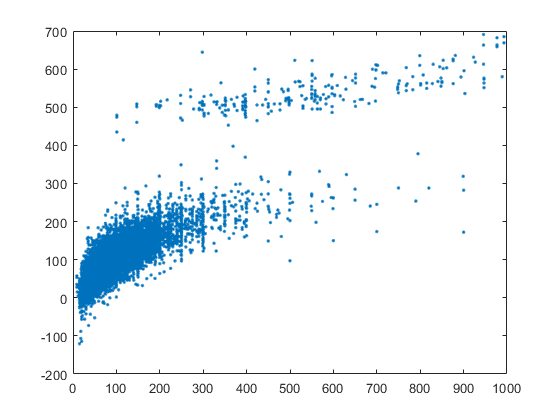

% plotting actual vs predicted price to see error/shape of distribution
% (the more linear, the more accurate)
plot(data_price_matrix, predicted_price, '.')

function possibles = possibles_mv(data)
    possibles = {};
    for i=1:size(data, 1)
        for j=1:size(data{i}, 2)
            if ~any(strcmp(possibles, data{i}{j}))
                possibles{size(possibles,2)+1} = data{i}{j};
            end
        end
    end
end

function possibles = possibles_sv(data)
    possibles = {};
    for i=1:size(data, 1)
        if ~any(strcmp(possibles, data{i}))
            possibles{size(possibles,2)+1} = data{i};
        end
    end
end

function categorized = categorize_mv(data, possibles)
    % input: cell array of cell array of strings
    categorized = zeros(1, size(possibles, 2));
    for i=1:size(data, 1)
        for j=1:size(data{i}, 2)
            one_val = strcmp(possibles, data{i}{j});
            categorized = categorized + one_val;
        end
    end
end

function categorized = categorize_sv(data, possibles)
    % input: cell array of strings
    categorized = zeros(1, size(possibles, 2));
    size(data);
    for i=1:size(data, 1)
        one_val = strcmp(possibles, data{i});
        categorized = categorized + one_val;
    end
end

function table = matrix_to_table(matrix, col_names)
    table = array2table(matrix);
    %ensures there are to spaces in column names
    col_names = strrep(col_names,' ','_');
    table.Properties.VariableNames(1:10) = col_names;
end

function [one_hot_m, top_attributes] = one_hot_encoding_mv(col_data, row_len, top_len)
    % Multiple vars(mv) calculations: given a string of attributes stringed
    % together, generate a one-hot table
    % col_data: column used to perform one hot encoding. 
    % col_len: length of matrix, typically the entire data set
    % top_len: grab the top x most common attributes
    
    % splits the string by commas into string arrays contained by cell arrays
    % and gets the 1st nth properties in the array. 
    data = regexp(col_data, ',', 'split');
    data = data(1:row_len,:);
    
    % this gets the all possible types in this column listed on the first 100 properties
    possibles = possibles_mv(data);
    % example of one row processed through one-hot encoding:
    % one_hot = num2cell(categorize_mv(data(2,:), possibles));
    
    % combined version shows most common amenities. The following section gets
    % the top top_len amenities
    one_hot_combined = num2cell(categorize_mv(data, possibles));
    C_stacked = [one_hot_combined; possibles];
    C_transpose = transpose(sortrows(transpose(C_stacked), 'descend'));
    
    % rounds down num of components to make it not exceed maximum
    top_len = min(top_len, size(C_transpose, 2));
    top_attributes = C_transpose(2, 1:top_len);
    
    % creates a matrix with one hot encoding of amenities. 
    % row: properties, columns: amenities
    one_hot_m = categorize_mv(data(1,:), top_attributes);
    for i = 2:size(data, 1)
        one_hot_row = categorize_mv(data(i,:), top_attributes);
        one_hot_m(i,:) = one_hot_row;
    end
end

function [one_hot_m, top_attributes] = one_hot_encoding_sv(data, row_len, top_len)
    % Single vars(sv) calculations: given one attribute per row, generate a one-hot table
    % col_data: column used to perform one hot encoding. 
    % col_len: length of matrix, typically the entire data set
    % top_len: grab the top x most common attributes
    
    % gets the 1st nth properties in the array. 
    data = data(1:row_len,:);
    
    % this gets the all possible types in this column listed on the first 100 properties
    possibles = possibles_sv(data);
    % example of one row processed through one-hot encoding:
    % one_hot = num2cell(categorize_sv(data(2,:), possibles));
    
    % combined version shows most common amenities. The following section gets
    % the top top_len amenities
    one_hot_combined = num2cell(categorize_sv(data, possibles));
    C_stacked = [one_hot_combined; possibles];
    C_transpose = transpose(sortrows(transpose(C_stacked), 'descend'));
    
    % rounds down num of components to make it not exceed maximum
    top_len = min(top_len, size(C_transpose, 2));
    top_attributes = C_transpose(2, 1:top_len);
    
    % creates a matrix with one hot encoding of amenities. 
    % row: properties, columns: amenities
    one_hot_m = categorize_sv(data(1,:), top_attributes);
    for i = 2:size(data, 1)
        one_hot_row = categorize_sv(data(i,:), top_attributes);
        one_hot_m(i,:) = one_hot_row;
    end
end